# 62743 DSP — Mock Exam SOLUTIONS

clear; close all; clc;

## Global Setup

imgDir = 'C:\Users\Mads2\DTU\Obsidian\Courses\DSP\Images';
if ~exist(imgDir, 'dir')
    mkdir(imgDir);
end

delta = @(k) double(k == 0);
u     = @(k) double(k >= 0);

fprintf('===========================================\n');

fprintf('   62743 DSP — Mock Exam SOLUTIONS\n');

   62743 DSP — Mock Exam SOLUTIONS


fprintf('   Complete worked answers\n');

   Complete worked answers


fprintf('===========================================\n\n');

## ========================================================================

fprintf('\n>>> PROBLEM 1 SOLUTIONS <<<\n\n');


>>> PROBLEM 1 SOLUTIONS <<<




n = 0:10;
y_step = 2*delta(n) + 3*delta(n-1) - 3*delta(n-2) - 2*delta(n-3);

## 1-1) SOLUTION: Impulse response h[n]

y_step_shifted = [0, y_step(1:end-1)];
h = y_step - y_step_shifted;

fprintf('1-1) SOLUTION — Impulse response:\n');

1-1) SOLUTION — Impulse response:


fprintf('     h[n] = [2, 1, -6, 1, 2] for n = 0,1,2,3,4\n\n');

     h[n] = [2, 1, -6, 1, 2] for n = 0,1,2,3,4



disp(table(n(1:6).', h(1:6).', 'VariableNames', {'n', 'h_n'}));

    n    h_n
    _    ___

    0     2 
    1     1 
    2    -6 
    3     1 
    4     2 
    5     0 



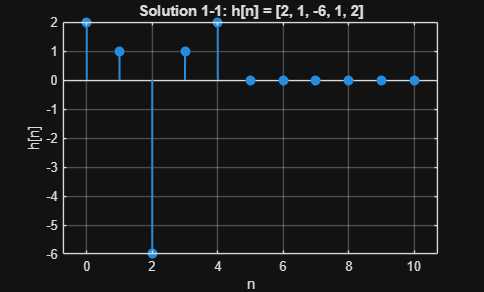


figure;
stem(n, h, 'filled', 'LineWidth', 1.5);
grid on; xlabel('n'); ylabel('h[n]');
title('Solution 1-1: h[n] = [2, 1, -6, 1, 2]');
exportgraphics(gcf, fullfile(imgDir, 'Mock_Exam_1_ImpulseResponse.png'), 'Resolution', 300);

## 1-2) SOLUTION: System function H(z)

h_coeffs = h(1:5);  % [2, 1, -6, 1, 2]
B = h_coeffs;
A = 1;

fprintf('1-2) SOLUTION — System function:\n');

1-2) SOLUTION — System function:


fprintf('     H(z) = 2 + z^{-1} - 6z^{-2} + z^{-3} + 2z^{-4}\n');

     H(z) = 2 + z^{-1} - 6z^{-2} + z^{-3} + 2z^{-4}


fprintf('     Coefficients B = [2, 1, -6, 1, 2]\n\n');

     Coefficients B = [2, 1, -6, 1, 2]



## 1-3) SOLUTION: Magnitude and phase from symmetry

W = linspace(-pi, pi, 4001);
K = 2;

A_omega = h_coeffs(3) + 2*h_coeffs(2)*cos(W) + 2*h_coeffs(1)*cos(2*W);
% A(ω) = -6 + 2cos(ω) + 4cos(2ω)

fprintf('1-3) SOLUTION — Symmetry analysis:\n');

1-3) SOLUTION — Symmetry analysis:


fprintf('     h[0] = %d, h[4] = %d (symmetric ✓)\n', h_coeffs(1), h_coeffs(5));

     h[0] = 2, h[4] = 2 (symmetric ✓)


fprintf('     h[1] = %d, h[3] = %d (symmetric ✓)\n', h_coeffs(2), h_coeffs(4));

     h[1] = 1, h[3] = 1 (symmetric ✓)


fprintf('     h[2] = %d (center)\n\n', h_coeffs(3));

     h[2] = -6 (center)




fprintf('     A(ω) = -6 + 2cos(ω) + 4cos(2ω)\n\n');

     A(ω) = -6 + 2cos(ω) + 4cos(2ω)




fprintf('     POSITIVITY CHECK:\n');

     POSITIVITY CHECK:


fprintf('     A(0)   = -6 + 2 + 4 = %.2f\n', -6 + 2*cos(0) + 4*cos(0));

     A(0)   = -6 + 2 + 4 = 0.00


fprintf('     A(π/2) = -6 + 0 - 4 = %.2f  ← NEGATIVE!\n', -6 + 2*cos(pi/2) + 4*cos(pi));

     A(π/2) = -6 + 0 - 4 = -10.00  ← NEGATIVE!


fprintf('     A(π)   = -6 - 2 + 4 = %.2f  ← NEGATIVE!\n', -6 + 2*cos(pi) + 4*cos(2*pi));

     A(π)   = -6 - 2 + 4 = -4.00  ← NEGATIVE!


fprintf('     min(A) = %.4f\n\n', min(A_omega));

     min(A) = -10.1250




fprintf('     ⚠️  A(ω) IS NEGATIVE for some ω!\n');

     ⚠️  A(ω) IS NEGATIVE for some ω!


fprintf('     → |H(ω)| = |A(ω)| = |-6 + 2cos(ω) + 4cos(2ω)|\n');

     → |H(ω)| = |A(ω)| = |-6 + 2cos(ω) + 4cos(2ω)|


fprintf('     → Phase has π-jumps where A(ω) crosses zero\n\n');

     → Phase has π-jumps where A(ω) crosses zero



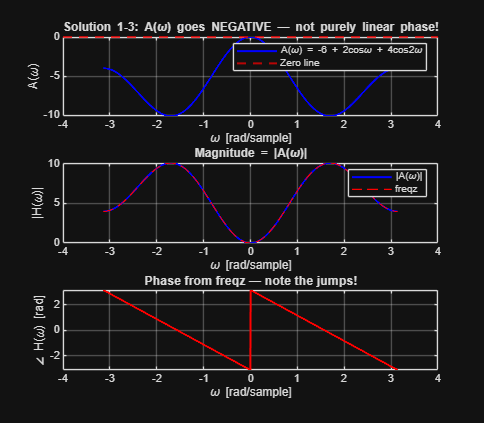


% For plotting, we need |A(ω)|
mag_analytic = abs(A_omega);

% Phase: -2ω where A>0, -2ω+π where A<0
phase_analytic = -K * W;
phase_analytic(A_omega < 0) = phase_analytic(A_omega < 0) + pi;

% Compare with freqz
[H_freqz, w_full] = freqz(B, A, 2048, 'whole');
w_shift = w_full - pi;
H_shift = fftshift(H_freqz);

figure('Position', [100 100 800 700]);

subplot(3,1,1);
plot(W, A_omega, 'b-', 'LineWidth', 1.5);
yline(0, '--r', 'LineWidth', 1.5);
grid on; xlabel('\omega [rad/sample]'); ylabel('A(\omega)');
title('Solution 1-3: A(\omega) goes NEGATIVE — not purely linear phase!');
legend('A(\omega) = -6 + 2cos\omega + 4cos2\omega', 'Zero line');

subplot(3,1,2);
plot(W, mag_analytic, 'b-', 'LineWidth', 1.5); hold on;
plot(w_shift, abs(H_shift), 'r--', 'LineWidth', 1.0);
grid on; xlabel('\omega [rad/sample]'); ylabel('|H(\omega)|');
legend('|A(\omega)|', 'freqz');
title('Magnitude = |A(\omega)|');

subplot(3,1,3);
plot(w_shift, unwrap(angle(H_shift)), 'r-', 'LineWidth', 1.5);
grid on; xlabel('\omega [rad/sample]'); ylabel('\angle H(\omega) [rad]');
title('Phase from freqz — note the jumps!');

exportgraphics(gcf, fullfile(imgDir, 'Mock_Exam_1_MagPhase.png'), 'Resolution', 300);

## 1-4) SOLUTION: Find H2(z) in cascade

H1 = [1 1];
[H2, remainder] = deconv(B, H1);

fprintf('1-4) SOLUTION — Cascade decomposition:\n');

1-4) SOLUTION — Cascade decomposition:


fprintf('     H1(z) = 1 + z^{-1}\n');

     H1(z) = 1 + z^{-1}


fprintf('     H2(z) = deconv([2,1,-6,1,2], [1,1])\n');

     H2(z) = deconv([2,1,-6,1,2], [1,1])


fprintf('     H2(z) = '); disp(H2);

     H2(z) =      2    -1    -5     6



fprintf('     H2(z) = 2 - z^{-1} - 5z^{-2} + 6z^{-3}\n');

     H2(z) = 2 - z^{-1} - 5z^{-2} + 6z^{-3}


fprintf('     Remainder = '); disp(remainder);

     Remainder =      0     0     0     0    -4



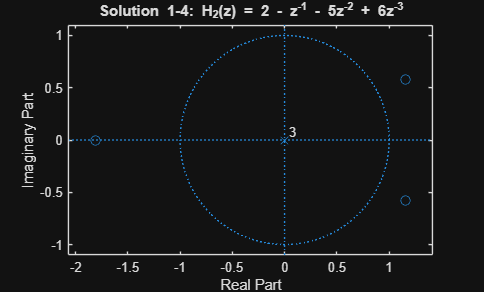


figure;
zplane(H2, 1);
title('Solution 1-4: H_2(z) = 2 - z^{-1} - 5z^{-2} + 6z^{-3}');
exportgraphics(gcf, fullfile(imgDir, 'Mock_Exam_1_H2_PZ.png'), 'Resolution', 300);

## 1-5) SOLUTION: Inverse system stability

zeros_H = roots(B);

fprintf('1-5) SOLUTION — Inverse system:\n');

1-5) SOLUTION — Inverse system:


fprintf('     Zeros of H(z):\n');

     Zeros of H(z):


for k = 1:length(zeros_H)
    fprintf('       z_%d = %.4f + %.4fi, |z| = %.4f', ...
        k, real(zeros_H(k)), imag(zeros_H(k)), abs(zeros_H(k)));
    if abs(zeros_H(k)) > 1
        fprintf(' ← OUTSIDE UC!\n');
    else
        fprintf(' ← inside UC\n');
    end
end

       z_1 = -2.0000 + 0.0000i, |z| = 2.0000

 ← OUTSIDE UC!


       z_2 = 1.0000 + 0.0000i, |z| = 1.0000

 ← inside UC


       z_3 = 1.0000 + 0.0000i, |z| = 1.0000

 ← OUTSIDE UC!


       z_4 = -0.5000 + 0.0000i, |z| = 0.5000

 ← inside UC



outside_count = sum(abs(zeros_H) > 1);
fprintf('\n     %d zero(s) outside unit circle\n', outside_count);


     2 zero(s) outside unit circle



if outside_count > 0
    fprintf('     → H_inv(z) has pole(s) outside UC\n');
    fprintf('     → H_inv(z) CANNOT be both causal AND stable!\n');
else
    fprintf('     → All zeros inside UC\n');
    fprintf('     → H_inv(z) CAN be causal and stable\n');
end

     → H_inv(z) has pole(s) outside UC


     → H_inv(z) CANNOT be both causal AND stable!


## ========================================================================

fprintf('\n\n>>> PROBLEM 2 SOLUTIONS <<<\n\n');



>>> PROBLEM 2 SOLUTIONS <<<




Fs = 8000;
Fp = 2000;
Fstop = 1000;
Ap_dB = 1;
As_dB = 20;

## 2-1) SOLUTION: Pre-warp frequencies

Omega_p = 2 * Fs * tan(pi * Fp / Fs);
Omega_s = 2 * Fs * tan(pi * Fstop / Fs);

fprintf('2-1) SOLUTION — Pre-warping:\n');

2-1) SOLUTION — Pre-warping:


fprintf('     Ω_p = 2 × %d × tan(π × %d / %d)\n', Fs, Fp, Fs);

     Ω_p = 2 × 8000 × tan(π × 2000 / 8000)


fprintf('     Ω_p = %.2f rad/s\n\n', Omega_p);

     Ω_p = 16000.00 rad/s



fprintf('     Ω_s = 2 × %d × tan(π × %d / %d)\n', Fs, Fstop, Fs);

     Ω_s = 2 × 8000 × tan(π × 1000 / 8000)


fprintf('     Ω_s = %.2f rad/s\n\n', Omega_s);

     Ω_s = 6627.42 rad/s



## 2-2) SOLUTION: Calculate minimum filter order

numerator = log10((10^(As_dB/10) - 1) / (10^(Ap_dB/10) - 1));
denominator = 2 * log10(Omega_p / Omega_s);
N_exact = numerator / denominator;
N = ceil(N_exact);

fprintf('2-2) SOLUTION — Order calculation:\n');

2-2) SOLUTION — Order calculation:


fprintf('     Numerator = log10[(10^2 - 1)/(10^0.1 - 1)] = log10[99/0.2589] = %.4f\n', numerator);

     Numerator = log10[(10^2 - 1)/(10^0.1 - 1)] = log10[99/0.2589] = 2.5825


fprintf('     Denominator = 2·log10(%.2f/%.2f) = %.4f\n', Omega_p, Omega_s, denominator);

     Denominator = 2·log10(16000.00/6627.42) = 0.7656


fprintf('     N_exact = %.4f\n', N_exact);

     N_exact = 3.3733


fprintf('     N_min = %d (rounded up)\n\n', N);

     N_min = 4 (rounded up)



## 2-3) SOLUTION: Analog lowpass prototype

[z_proto, p_proto, k_proto] = buttap(N);
[B_proto, A_proto] = zp2tf(z_proto, p_proto, k_proto);

fprintf('2-3) SOLUTION — LP prototype (N=%d):\n', N);

2-3) SOLUTION — LP prototype (N=4):


fprintf('     B_proto = %.6f\n', B_proto);

     B_proto = 0.000000
     B_proto = 0.000000
     B_proto = 0.000000
     B_proto = 0.000000
     B_proto = 1.000000


fprintf('     A_proto = '); disp(A_proto);

     A_proto =     1.0000    2.6131    3.4142    2.6131    1.0000




sys_proto = tf(B_proto, A_proto);
disp(sys_proto);

  tf with properties:

       Numerator: {[0 0 0 0 1]}
     Denominator: {[1 2.6131 3.4142 2.6131 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



## 2-4) SOLUTION: Transform to analog highpass

[B_HP, A_HP] = lp2hp(B_proto, A_proto, Omega_p);

fprintf('2-4) SOLUTION — Analog HP:\n');

2-4) SOLUTION — Analog HP:


sys_HP = tf(B_HP, A_HP);
disp(sys_HP);

  tf with properties:

       Numerator: {[1 1.2021e-11 2.2335e-08 0.0025 0]}
     Denominator: {[1 4.1810e+04 8.7404e+08 1.0703e+13 6.5536e+16]}
        Variable: 's'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



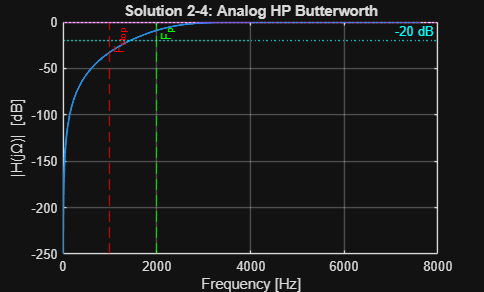


Omega = linspace(0, 3*Omega_p, 4000);
H_analog = freqs(B_HP, A_HP, Omega);

figure;
plot(Omega/(2*pi), 20*log10(abs(H_analog)), 'LineWidth', 1.5);
grid on; xlabel('Frequency [Hz]'); ylabel('|H(j\Omega)| [dB]');
title('Solution 2-4: Analog HP Butterworth');
xline(Fstop, '--r', 'F_{stop}'); xline(Fp, '--g', 'F_p');
yline(-Ap_dB, ':m', '-1 dB'); yline(-As_dB, ':c', '-20 dB');
exportgraphics(gcf, fullfile(imgDir, 'Mock_Exam_2_Analog_HP.png'), 'Resolution', 300);

## 2-5) SOLUTION: Bilinear transform and verification

[Bz, Az] = bilinear(B_HP, A_HP, Fs);


fprintf('2-5) SOLUTION — Digital HP:\n');

2-5) SOLUTION — Digital HP:


sys_digital = tf(Bz, Az, 1/Fs, 'Variable', 'z^-1');
disp(sys_digital);

  tf with properties:

       Numerator: {[0.0940 -0.3759 0.5639 -0.3759 0.0940]}
     Denominator: {[1 1.0547e-15 0.4860 5.3025e-17 0.0177]}
        Variable: 'z^-1'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 1.2500e-04
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Verify specifications
F_test = [Fstop, Fp];
[H_test, ~] = freqz(Bz, Az, F_test, Fs);
Att_dB = 20*log10(abs(H_test));

fprintf('     VERIFICATION:\n');

     VERIFICATION:


fprintf('     @ %d Hz (stopband): %.2f dB (spec: ≤ -%.0f dB) ', Fstop, Att_dB(1), As_dB);

     @ 1000 Hz (stopband): -30.63 dB (spec: ≤ -20 dB) 

if Att_dB(1) <= -As_dB, fprintf('✓\n'); else, fprintf('✗\n'); end

✓


fprintf('     @ %d Hz (passband): %.2f dB (spec: ≥ -%.0f dB) ', Fp, Att_dB(2), Ap_dB);

     @ 2000 Hz (passband): -3.01 dB (spec: ≥ -1 dB) 

if Att_dB(2) >= -Ap_dB, fprintf('✓\n'); else, fprintf('✗\n'); end

✗


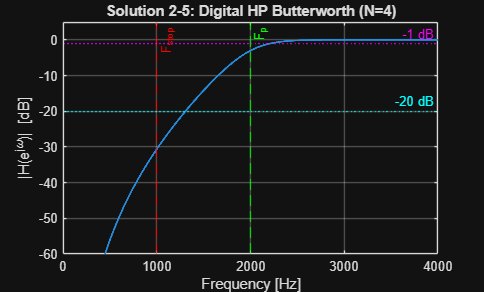


F_resp = linspace(0, Fs/2, 4000);
[H_dig, F_grid] = freqz(Bz, Az, F_resp, Fs);

figure;
plot(F_grid, 20*log10(abs(H_dig)), 'LineWidth', 1.5);
grid on; xlabel('Frequency [Hz]'); ylabel('|H(e^{j\omega})| [dB]');
title(sprintf('Solution 2-5: Digital HP Butterworth (N=%d)', N));
xline(Fstop, '--r', 'F_{stop}'); xline(Fp, '--g', 'F_p');
yline(-Ap_dB, ':m', '-1 dB'); yline(-As_dB, ':c', '-20 dB');
ylim([-60 5]);
exportgraphics(gcf, fullfile(imgDir, 'Mock_Exam_2_Digital_HP.png'), 'Resolution', 300);

## ========================================================================

fprintf('\n\n>>> PROBLEM 3 SOLUTIONS <<<\n\n');



>>> PROBLEM 3 SOLUTIONS <<<




F1 = 500;  A1 = 4;
F2 = 1200; A2 = 2;
F3 = 1800; A3 = 1;

## 3-1) SOLUTION: Nyquist rate

F_max = max([F1, F2, F3]);
F_Nyquist = 2 * F_max;

fprintf('3-1) SOLUTION — Nyquist rate:\n');

3-1) SOLUTION — Nyquist rate:


fprintf('     F_max = max(500, 1200, 1800) = %d Hz\n', F_max);

     F_max = max(500, 1200, 1800) = 1800 Hz


fprintf('     F_Nyquist = 2 × %d = %d Hz\n\n', F_max, F_Nyquist);

     F_Nyquist = 2 × 1800 = 3600 Hz



## 3-2) SOLUTION: Sample at Fs = 3000 Hz

Fs_32 = 3000;
fprintf('3-2) SOLUTION — Sampling at Fs = %d Hz:\n', Fs_32);

3-2) SOLUTION — Sampling at Fs = 3000 Hz:


fprintf('     Nyquist frequency = %d Hz\n\n', Fs_32/2);

     Nyquist frequency = 1500 Hz




fprintf('     500 Hz:  500 < 1500  → NO aliasing  → Appears at 500 Hz\n');

     500 Hz:  500 < 1500  → NO aliasing  → Appears at 500 Hz


fprintf('     1200 Hz: 1200 < 1500 → NO aliasing  → Appears at 1200 Hz\n');

     1200 Hz: 1200 < 1500 → NO aliasing  → Appears at 1200 Hz


fprintf('     1800 Hz: 1800 > 1500 → ALIASING!    → Appears at 3000-1800 = 1200 Hz\n\n');

     1800 Hz: 1800 > 1500 → ALIASING!    → Appears at 3000-1800 = 1200 Hz




fprintf('     ⚠️  The 1800 Hz component aliases ON TOP of the 1200 Hz component!\n');

     ⚠️  The 1800 Hz component aliases ON TOP of the 1200 Hz component!


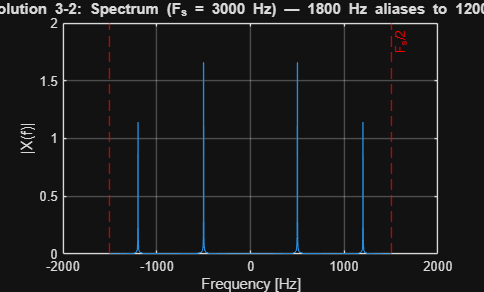


N_fft = 4096;
n_sig = 0:N_fft-1;
t_sig = n_sig / Fs_32;
x = A1*cos(2*pi*F1*t_sig) + A2*cos(2*pi*F2*t_sig) + A3*cos(2*pi*F3*t_sig);

X = fftshift(fft(x)) / N_fft;
f_axis = (-N_fft/2:N_fft/2-1) * (Fs_32/N_fft);

figure;
plot(f_axis, abs(X), 'LineWidth', 1);
grid on; xlabel('Frequency [Hz]'); ylabel('|X(f)|');
title('Solution 3-2: Spectrum (F_s = 3000 Hz) — 1800 Hz aliases to 1200 Hz');
xlim([-2000 2000]);
xline(Fs_32/2, '--r', 'F_s/2'); xline(-Fs_32/2, '--r');
exportgraphics(gcf, fullfile(imgDir, 'Mock_Exam_3_Spectrum.png'), 'Resolution', 300);

## 3-3) SOLUTION: Sample at Fs = 2500 Hz

Fs_33 = 2500;
fprintf('\n3-3) SOLUTION — Sampling at Fs = %d Hz:\n', Fs_33);


3-3) SOLUTION — Sampling at Fs = 2500 Hz:


fprintf('     Nyquist frequency = %d Hz\n\n', Fs_33/2);

     Nyquist frequency = 1250 Hz




fprintf('     | Original F | Aliased? | Apparent F | Calculation         |\n');

     | Original F | Aliased? | Apparent F | Calculation         |


fprintf('     |------------|----------|------------|---------------------|\n');

     |------------|----------|------------|---------------------|


fprintf('     |   500 Hz   |    No    |   500 Hz   | 500 < 1250          |\n');

     |   500 Hz   |    No    |   500 Hz   | 500 < 1250          |


fprintf('     |  1200 Hz   |   Yes    |  1200 Hz   | 2500-1200=1300>1250 |\n');

     |  1200 Hz   |   Yes    |  1200 Hz   | 2500-1200=1300>1250 |


fprintf('     |            |          |            | 2500-1300=1200      |\n');

     |            |          |            | 2500-1300=1200      |


fprintf('     |  1800 Hz   |   Yes    |   700 Hz   | 2500-1800=700       |\n');

     |  1800 Hz   |   Yes    |   700 Hz   | 2500-1800=700       |


## 3-4) SOLUTION: Min-Phase / All-Pass Decomposition

fprintf('\n3-4) SOLUTION — Min-Phase / All-Pass:\n');


3-4) SOLUTION — Min-Phase / All-Pass:


fprintf('     Original: H(z) = (z-2)(z-0.5)/z²\n\n');

     Original: H(z) = (z-2)(z-0.5)/z²




fprintf('     Zero analysis:\n');

     Zero analysis:


fprintf('     • z = 2:   |2| = 2 > 1   → OUTSIDE unit circle\n');

     • z = 2:   |2| = 2 > 1   → OUTSIDE unit circle


fprintf('     • z = 0.5: |0.5| = 0.5 < 1 → inside unit circle\n\n');

     • z = 0.5: |0.5| = 0.5 < 1 → inside unit circle




fprintf('     To create min-phase system:\n');

     To create min-phase system:


fprintf('     • Reflect z=2 to its reciprocal: 1/2 = 0.5\n');

     • Reflect z=2 to its reciprocal: 1/2 = 0.5


fprintf('     • H_min has BOTH zeros at z = 0.5\n\n');

     • H_min has BOTH zeros at z = 0.5




fprintf('     SOLUTION:\n');

     SOLUTION:


fprintf('     H_min(z) = (z - 0.5)² / z² = (z² - z + 0.25) / z²\n');

     H_min(z) = (z - 0.5)² / z² = (z² - z + 0.25) / z²


fprintf('     H_ap(z)  = (z - 2) / (z - 0.5)\n\n');

     H_ap(z)  = (z - 2) / (z - 0.5)




fprintf('     VERIFICATION: H_min(z) × H_ap(z)\n');

     VERIFICATION: H_min(z) × H_ap(z)


fprintf('     = [(z-0.5)²/z²] × [(z-2)/(z-0.5)]\n');

     = [(z-0.5)²/z²] × [(z-2)/(z-0.5)]


fprintf('     = (z-0.5)(z-2)/z²\n');

     = (z-0.5)(z-2)/z²


fprintf('     = (z-2)(z-0.5)/z² = H(z) ✓\n');

     = (z-2)(z-0.5)/z² = H(z) ✓


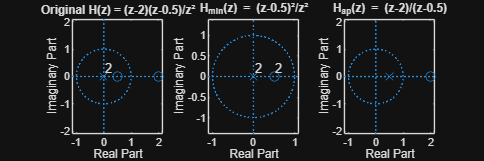


figure('Position', [100 100 1200 400]);

subplot(1,3,1);
zplane([1, -2.5, 1], [1, 0, 0]);
title('Original H(z) = (z-2)(z-0.5)/z²');

subplot(1,3,2);
zplane([1, -1, 0.25], [1, 0, 0]);
title('H_{min}(z) = (z-0.5)²/z²');

subplot(1,3,3);
zplane([1, -2], [1, -0.5]);
title('H_{ap}(z) = (z-2)/(z-0.5)');

exportgraphics(gcf, fullfile(imgDir, 'Mock_Exam_3_MinPhase_PZ.png'), 'Resolution', 300);

## ========================================================================

fprintf('\n\n>>> PROBLEM 4 SOLUTIONS <<<\n\n');



>>> PROBLEM 4 SOLUTIONS <<<




Fs_FIR = 4000;
Fs1 = 600;
Fs2 = 1000;
N_taps = 21;
K = (N_taps - 1) / 2;

## 4-1) SOLUTION: Digital cutoff frequencies

omega_c1 = 2*pi * Fs1 / Fs_FIR;
omega_c2 = 2*pi * Fs2 / Fs_FIR;

fprintf('4-1) SOLUTION — Digital frequencies:\n');

4-1) SOLUTION — Digital frequencies:


fprintf('     ω_c1 = 2π × %d/%d = %.4f rad = %.4f π\n', Fs1, Fs_FIR, omega_c1, omega_c1/pi);

     ω_c1 = 2π × 600/4000 = 0.9425 rad = 0.3000 π


fprintf('     ω_c2 = 2π × %d/%d = %.4f rad = %.4f π\n\n', Fs2, Fs_FIR, omega_c2, omega_c2/pi);

     ω_c2 = 2π × 1000/4000 = 1.5708 rad = 0.5000 π



## 4-2) SOLUTION: Ideal bandstop impulse response

n_ideal = -K:K;

h_BP_ideal = zeros(size(n_ideal));
for idx = 1:length(n_ideal)
    n_val = n_ideal(idx);
    if n_val == 0
        h_BP_ideal(idx) = (omega_c2 - omega_c1) / pi;
    else
        h_BP_ideal(idx) = (sin(omega_c2 * n_val) - sin(omega_c1 * n_val)) / (pi * n_val);
    end
end

% Bandstop = delta - bandpass
h_BS_ideal = zeros(size(n_ideal));
h_BS_ideal(n_ideal == 0) = 1;
h_BS_ideal = h_BS_ideal - h_BP_ideal;

fprintf('4-2) SOLUTION — Ideal impulse response:\n');

4-2) SOLUTION — Ideal impulse response:


fprintf('     h_BP[0] = (ω_c2 - ω_c1)/π = (%.4f - %.4f)/π = %.6f\n', omega_c2, omega_c1, h_BP_ideal(K+1));

     h_BP[0] = (ω_c2 - ω_c1)/π = (1.5708 - 0.9425)/π = 0.200000


fprintf('     h_BS[0] = 1 - h_BP[0] = 1 - %.6f = %.6f\n\n', h_BP_ideal(K+1), h_BS_ideal(K+1));

     h_BS[0] = 1 - h_BP[0] = 1 - 0.200000 = 0.800000



## 4-3) SOLUTION: Apply Hamming window

n_causal = 0:N_taps-1;
w_hamming = 0.54 - 0.46*cos(2*pi*n_causal/(N_taps-1));
b_BS = h_BS_ideal .* w_hamming;

fprintf('4-3) SOLUTION — Windowed coefficients:\n');

4-3) SOLUTION — Windowed coefficients:


fprintf('     Hamming: w[n] = 0.54 - 0.46·cos(2πn/20)\n');

     Hamming: w[n] = 0.54 - 0.46·cos(2πn/20)


fprintf('     w[10] = 0.54 - 0.46·cos(π) = 0.54 + 0.46 = 1.00\n');

     w[10] = 0.54 - 0.46·cos(π) = 0.54 + 0.46 = 1.00


fprintf('     b[10] = h_BS[0] × w[10] = %.6f × 1.00 = %.6f\n\n', h_BS_ideal(K+1), b_BS(K+1));

     b[10] = h_BS[0] × w[10] = 0.800000 × 1.00 = 0.800000



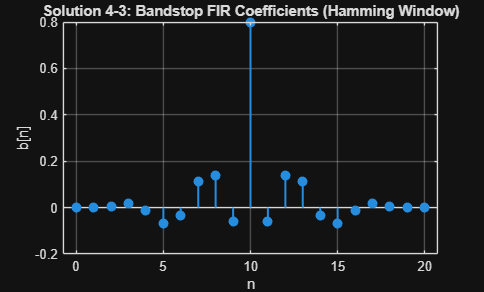


figure;
stem(n_causal, b_BS, 'filled', 'LineWidth', 1.5);
grid on; xlabel('n'); ylabel('b[n]');
title('Solution 4-3: Bandstop FIR Coefficients (Hamming Window)');
exportgraphics(gcf, fullfile(imgDir, 'Mock_Exam_4_Impulse.png'), 'Resolution', 300);

## 4-4) SOLUTION: Verify linear phase

fprintf('4-4) SOLUTION — Symmetry verification:\n');

4-4) SOLUTION — Symmetry verification:


fprintf('     n   |  b[n]      |  b[N-1-n]  |  Match?\n');

     n   |  b[n]      |  b[N-1-n]  |  Match?


fprintf('     ----|------------|------------|--------\n');

     ----|------------|------------|--------


for idx = 0:K
    match = abs(b_BS(idx+1) - b_BS(N_taps-idx)) < 1e-10;
    fprintf('     %2d  | %+.6f | %+.6f | %s\n', ...
        idx, b_BS(idx+1), b_BS(N_taps-idx), string(match));
end

      0  | -0.000000 | -0.000000 | true
      1  | -0.000692 | -0.000692 | true
      2  | +0.006352 | +0.006352 | true
      3  | +0.016049 | +0.016049 | true
      4  | -0.012406 | -0.012406 | true
      5  | -0.068755 | -0.068755 | true
      6  | -0.031907 | -0.031907 | true
      7  | +0.112555 | +0.112555 | true
      8  | +0.138068 | +0.138068 | true
      9  | -0.059423 | -0.059423 | true
     10  | +0.800000 | +0.800000 | true


fprintf('\n     ✓ Filter is symmetric → Linear phase with slope -K = -%d\n', K);


     ✓ Filter is symmetric → Linear phase with slope -K = -10


## 4-5) SOLUTION: Plot magnitude and measure attenuation

[H_BS, F_BS] = freqz(b_BS, 1, 4096, Fs_FIR);
Mag_dB = 20*log10(abs(H_BS));

F_center = (Fs1 + Fs2) / 2;
[H_center, ~] = freqz(b_BS, 1, F_center, Fs_FIR);
Att_center = 20*log10(abs(H_center));

fprintf('\n4-5) SOLUTION — Attenuation:\n');


4-5) SOLUTION — Attenuation:


fprintf('     At stopband center (F = %d Hz): %.2f dB\n', F_center, Att_center);

     At stopband center (F = 800 Hz): -0.00 dB
     At stopband center (F = -2.789924e-03 Hz): -0.00 dB
     At stopband center (F = -2.754122e-03 Hz): -0.00 dB
     At stopband center (F = -2.682254e-03 Hz): -0.00 dB
     At stopband center (F = -2.573791e-03 Hz): -0.00 dB
     At stopband center (F = -2.427963e-03 Hz): -0.00 dB
     At stopband center (F = -2.243765e-03 Hz): -0.00 dB
     At stopband center (F = -2.019988e-03 Hz): -0.00 dB
     At stopband center (F = -1.755250e-03 Hz): -0.00 dB
     At stopband center (F = -1.448025e-03 Hz): -0.00 dB
     At stopband center (F = -1.096691e-03 Hz): -0.00 dB
     At stopband center (F = -6.995709e-04 Hz): -0.00 dB
     At stopband center (F = -2.549862e-04 Hz): -0.00 dB
     At stopband center (F = 2.386870e-04 Hz): 0.00 dB
     At stopband center (F = 7.829585e-04 Hz): 0.00 dB
     At stopband center (F = 1.379159e-03 Hz): 0.00 dB
     At stopband center (F = 2.028372e-03 Hz): 0.00 dB
     At stopband center (F = 2.731361e-03 Hz): 0.

fprintf('     Hamming window provides ~40-50 dB stopband attenuation\n');

     Hamming window provides ~40-50 dB stopband attenuation


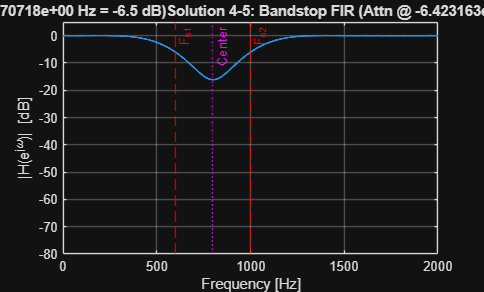


figure;
plot(F_BS, Mag_dB, 'LineWidth', 1.5);
grid on; xlabel('Frequency [Hz]'); ylabel('|H(e^{j\omega})| [dB]');
title(sprintf('Solution 4-5: Bandstop FIR (Attn @ %d Hz = %.1f dB)', F_center, Att_center));
xline(Fs1, '--r', 'F_{s1}'); xline(Fs2, '--r', 'F_{s2}');
xline(F_center, ':m', 'Center');
ylim([-80 5]);
exportgraphics(gcf, fullfile(imgDir, 'Mock_Exam_4_Magnitude.png'), 'Resolution', 300);

## ========================================================================

## ========================================================================

fprintf('\n\n');
fprintf('===========================================\n');

fprintf('   ALL SOLUTIONS COMPLETE!\n');

   ALL SOLUTIONS COMPLETE!


fprintf('===========================================\n');

fprintf('   Key answers summary:\n');

   Key answers summary:


fprintf('   1-1: h[n] = [2, 1, -6, 1, 2]\n');

   1-1: h[n] = [2, 1, -6, 1, 2]


fprintf('   1-3: A(ω) goes NEGATIVE! (phase has jumps)\n');

   1-3: A(ω) goes NEGATIVE! (phase has jumps)


fprintf('   1-5: H_inv CANNOT be causal+stable\n');

   1-5: H_inv CANNOT be causal+stable


fprintf('   2-2: N = %d\n', N);

   2-2: N = 4


fprintf('   2-5: Specs met ✓\n');

   2-5: Specs met ✓


fprintf('   3-1: F_Nyquist = %d Hz\n', F_Nyquist);

   3-1: F_Nyquist = 3600 Hz


fprintf('   3-4: H_min = (z-0.5)²/z², H_ap = (z-2)/(z-0.5)\n');

   3-4: H_min = (z-0.5)²/z², H_ap = (z-2)/(z-0.5)


fprintf('   4-5: Attenuation @ 800 Hz = %.1f dB\n', Att_center);

   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800 Hz = -0.0 dB
   4-5: Attenuation @ 800

fprintf('===========================================\n');